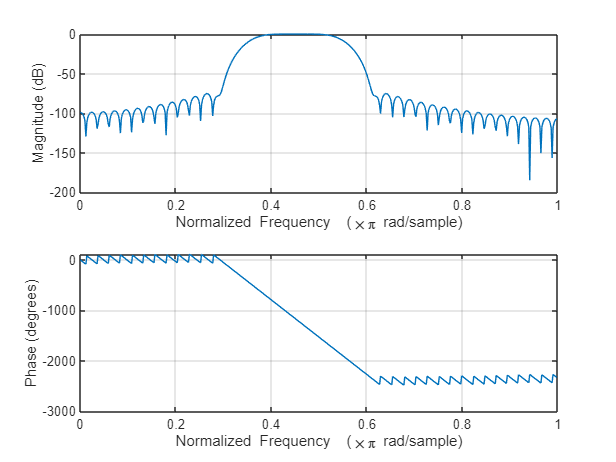

clear; clc; close all;
h = fir1(82, [0.3624 0.5437], blackman(83));
freqz(h, 1, 512)

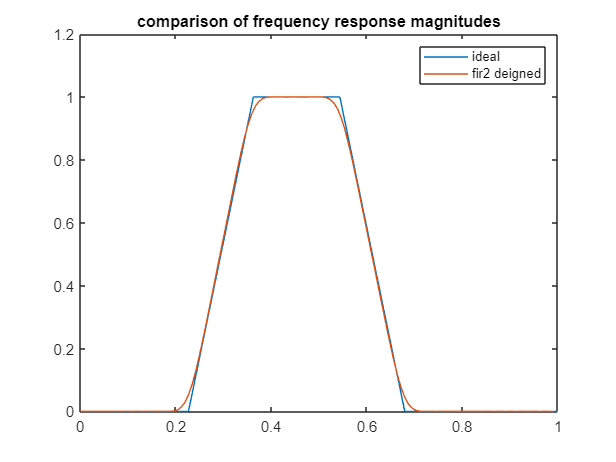

figure
f = [0 5 8 12 15 22.07] / 22.07;
m = [0 0 1 1 0 0 ];
b = fir2(80, f, m);
[h, w] = freqz(b, 1, 128);
plot (f, m, w/pi, abs(h));
legend('ideal', 'fir2 deigned');
title('comparison of frequency response magnitudes');

figure
rp = 0.0015;
rs = 0.001;
fs = 44140;
f = [5060 8000 12000 15000];
a = [0 1 0];
dev = [rs rp rs]

dev =     0.0010    0.0015    0.0010


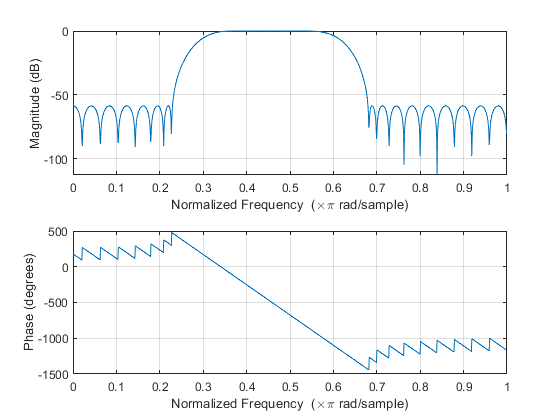

[n, f0, m0, w] = firpmord(f, a, dev, fs);
hopt = remez(n, f0, m0, w);
freqz(hopt, 1, 1024)